#### Load functions

% this file should be in the same directory as the /functions dir
% restoredefaultpath;
path = '~/Documents/Courses/Audio Signal Processing/Demo_FVN';
addpath([path '/matlab/functions']);

savefigs = true;
renderpath = [path '/render/img/stage/'];

% init color palette
baseHue = 0.3; % green = 0.3
rgb = genColors(baseHue, 0.1, nSeg);
showtitles = false;
plt_specHeight = 450;

### VN Generator

N = 6000;   % sequence length
f = 223;      % frequency (pulse density) in Hz
Fs = 48000;
Y = velvet(N, f, 48000);

#### Plot VN 

Td = Fs/f;          % pulse period
nPulse = N/Td;      % number of pulses in the sequence
x = find((Y~=0));
% plot the generated signal
stem(x, Y(x), 'k', 'filled', 'LineWidth', 1); hold on;

% plot the segment bounds
segBounds = [1:nPulse] * Td;
for i=1:length(segBounds)
    xline(segBounds(i), '--r', 'LineWidth', 0.5);
end

xlabel('Samples')
legend('VN sequence', 'period boundaries', 'Position',[0.65 0.78 0.26 0.082])
if showtitles; title("Velvet Noise sequence, pulse density " +f+ " Hz, Fs "+Fs); end;
axis tight
ylim([-1 1]*1.08)

plotSettingsTime(1); % set fontsize, linewidth
hold off;

if savefigs
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_vn_periods'], 'epsc')
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_vn_periods'], 'fig')
end

### Plot spectral estimate magnitudes

% select which data to plot
plt_data = mags_norm;
% data = mags;
% data = mags_rms_shift;

plot_rolloff_pnts = true;     % plot rolloff point markers?
nchan = size(plt_data, 2);    % number of channels available

seghop   = 13;                % hop between analysis channels for plotting a subset
plot_idx = (1:seghop:nchan);  % which channels to plot
nplot    = length(plot_idx);  % number of channels being plotted
plt_data = mags_norm(:, plot_idx);

plt = semilogx(lpfreqs, plt_data, "LineWidth", 1.5);

% generate colors for plot: hue_start, hue_span, num_plots
thisrgb = genColors(0.3, 0.1, nplot);

% plot cutoff markers
if ~plot_rolloff_pnts
    legend("Location", "SouthWest");
    legend('Position',[0.18 0.2 0.15 0.2]);
else
    
    hold on;
    
    % keep track of the plots for legend management
    plts = {};
    plts{1} = plt; % add the spectral lines plot (from prev block)
    
    for i = 1:length(idxs)
        plt = semilogx( ...
            freqs(idxs(i)), plt_data(idxs(i), i), ...
            "LineStyle", "none", "Marker", "*");
        plt.Annotation.LegendInformation.IconDisplayStyle = 'off';
        plts{i+1} = plt; % +1: plts{1} is the array of line plots
    end
    
    % colors
    colororder([thisrgb; thisrgb]); % repeated so line and marker colors match
    
    legend([ ...
        plts{1}(1) ... % first of the line plots
        plts{2} ...    % first of the rolloff markers
        ],[ ...
        "segment spectrum" ...
        string(rolloff) + " rolloff point" ...
        ]);
    legend("Location", "West");
    hold off;
end

colororder(thisrgb);
axis tight;    
xlim([500 20000]);
ylim([-50 2])

plotSettingsSpectrum()

if showtitles
    title(["Normalized spectral magnitude estimates, every "+seghop+" segments"])
end

if savefigs
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_-20dB_rolloff'], 'epsc')
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_-20dB_rolloff'], 'fig')
end

clear thisrgb plt_data nplot plot_idx seghop

### -20dB bandwidth frequency rolloff by window

plot(winStSamps / Fs, rollfreqs, 'Color', rgb(1,:), "LineWidth", 1.5);
xlabel('Time (s)')
ylabel('Frequency')
if showtitles
    title(strcat("-20dB bandwidth frequency rolloff, LPC order ", string(lpOrder)))
end

ylim([rollfreqs(end)*0.8 rollfreqs(1)*1.05])
plotH(plt_specHeight)
plotSettings(); % set fontsize, linewidth

if savefigs
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_freq_decay'], 'epsc')
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_freq_decay'], 'fig')
end

## All segments in line

figure();
% include initial silence where the first/early arrivals are
end_idx = seg_bounds(1)-1;
plot((1:end_idx) ./ Fs, zeros(end_idx, 1)); % inital (unsynthesized) part of response
hold on;
for i = 1:nSeg
    st_idx = seg_bounds(i); % seg_bounds is size nSeg+1
    end_idx = st_idx + seg_nsamp(i) - 1;
    plot((st_idx:end_idx) ./ Fs, segments{i});
end
for i = 1:nSeg
    st_idx = seg_bounds(i);
    xline(st_idx / Fs, "--r");
end
hold off;

% colororder([rgb; rgb]); % for dashed lines colored too
colororder([rgb]);

xlabel('Time [s]')
if showtitles
    title('Pori IR with -20dB bandwidth segment boundaries')
end

plotSettingsTime();

if savefigs
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_ir_segmented'], 'epsc')
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_ir_segmented'], 'fig')
end

clear plot_idxs cnt

## Segment divisions

nBounds = length(seg_bounds);

% interleave indicies
% y = nBounds:-1:1;
y = nSeg:-1:1;
y = [y; y];
y = y(:);
% y = y(1:end-2);

x = seg_bounds' / Fs;  % seg boundaries samples -> sec
x = [x; x];
x = x(:);
x = x(2:end-1);

% plot(x, y, 'LineWidth', 2);

z = [x y]';
z = z(:);
u = reshape(z, 4, length(z)/4); % clump into point pairs 
hold on;
for i = 1:length(u)
    p = u(:,i);
    if i < length(u)
        plot(p([1,3,3]), [p(2), p(4), p(4)-1], ...
            'Color', rgb(i,:), 'LineWidth', 2);
    else
        plot(p([1,3]), p([2,4]), ...
            'Color', rgb(i,:), 'LineWidth', 2);
    end
end
hold off;

if showtitles
    title({"Segment Boundaries", ...
        sprintf("Number of segments: %d", length(segStartIdxs))})
end

plotSettingsTime();
yticks([1 nSeg])
yticklabels(["last" "first"]);
ylabel('Segment index')
xlabel('Time [s]')
ylim([0, nSeg+1])

if savefigs
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_seg_lengths'], 'epsc')
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_seg_lengths'], 'fig')
end

clear nBounds

### Power of reference segments 

hold on;
plt = plot(reference_gains_norm, 'Color', 0.9*[1 1 1]);
plt.Annotation.LegendInformation.IconDisplayStyle = 'off';
plt = plot(vn_seq_gains_norm, 'Color', 0.9*[1 1 1]);
plt.Annotation.LegendInformation.IconDisplayStyle = 'off';

for i = 1:nSeg
    col = rgb(i, :);
    plt1 = plot(i, reference_gains_norm(i), 'o', ...
        'MarkerEdgeColor', col, 'MarkerFaceColor', col, ...
        'MarkerSize', 7);
    plt2 = plot(i, vn_seq_gains_norm(i), 'v', ...
        'MarkerEdgeColor', col, 'MarkerFaceColor', col, ...
        'MarkerSize', 7);
    if i>1
        plt1.Annotation.LegendInformation.IconDisplayStyle = 'off';
        plt2.Annotation.LegendInformation.IconDisplayStyle = 'off';
    end
end
hold off;

legend(["RIR segments" "VN sequences"], "Location", "west")
legend('Position',[0.17 0.17 0.17 0.1]);
xlabel("Segment index");
ylabel("Magnitude (dB)");
xlim([0 nSeg+1])
ylim([-160 5])
if showtitles
    title("Signal power of RIR segments and VN sequences")
end

plotH(plt_specHeight)
plotSettings();

if savefigs
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_pwr_contour'], 'epsc')
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_pwr_contour'], 'fig')
end

clear plt plt1 plt2

### Differential filter gains

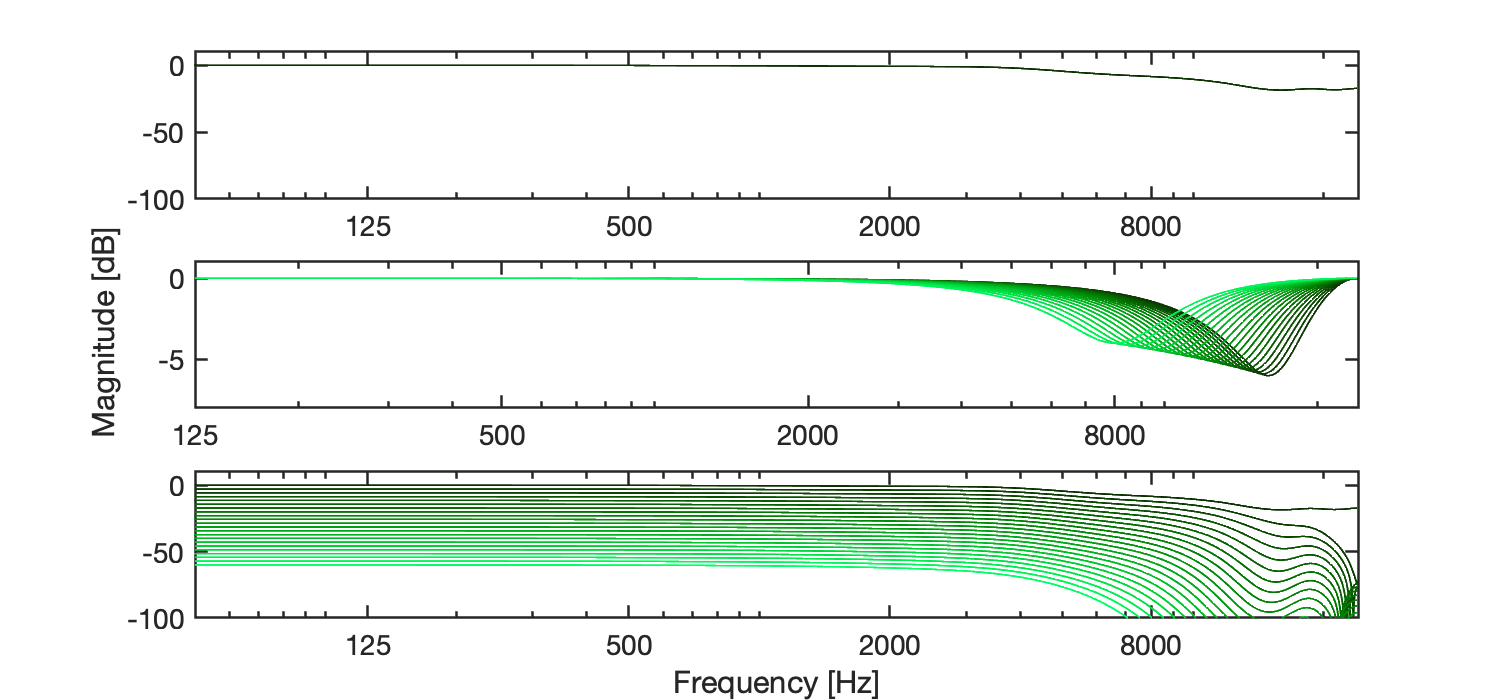

% filterplot(Bcolor, Acolor, Bdiff, Adiff, Fs, makeup_gains - max(makeup_gains));
filterplot(Bcolor, Acolor, Bdiff, Adiff, Fs, linspace(0, -60, nSeg));


% plotSettingsSpectrum(); % set fontsize, linewidth
if showtitles
    sgtitle(["H1 coloration filter, differential filters, filter cascade, by segment"])
end

if savefigs
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_diff_filts'], 'epsc')
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_diff_filts'], 'fig')
end

### All-pass Response

An example of the effect of 

a_ap = 0.65;                    % all-pass coefficient
% d_ap = [ 225, 341, 441, 556 ]; % all-pass delays
d_ap = [ 225, 341, 413, 537 ]; % all-pass delays
d_aps = "";
for i = 1:length(d_ap)
    d_aps = d_aps + " " +d_ap(i);
end
sig = [1; zeros(49, 1)];

% NOTE: this will determine the length of the returned signal, based on 
% and energy decay tail cutoff point. 
rolloff_threshold = -70;

for del = d_ap
    sig = schrdAllpass(sig, a_ap, del, rolloff_threshold);
end

x = (1:length(sig)) .* 1000 ./ Fs ; % ms
% x = 1:length(sig);                % samples

plot(x, max(mag2db(abs(sig)), -70), 'r')
% plot(x, abs(sig)); % abs(sig)

if showtitles
    title("All-pass cascade IR, a = "+a_ap+", M = "+d_aps);
end

plotSettingsTime(); % set fontsize, linewidth
% axis tight
% xlim([-2 45])
axis([-10 200 -70 -8])
% axis([-20 450 -100 -25])
ylabel("Magnitude [dB]");
xlabel("Time (ms)")

if savefigs
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_ap_response'], 'epsc')
    saveas(gcf,[renderpath datestr(now,'DDHHMMSS') '_ap_response'], 'fig')
end
clear sig x Ms a_AP

### FFT of a tap

idx =12;
plotFFT(taps(:,idx), 4096, Fs)
clear idx

### One tap

idx = 2;
plotsig = taps(:,idx);
plotsig = abs(plotsig);
plot(plotsig, 'LineWidth', 1); legend();
clear plotsig idx

#### Plot the IR (CHECK IF GAIN WAS APPLIED)

plotsig = summed_ir;
plotsig = abs(plotsig);
plotsig = plotsig / max(plotsig);
% plotsig = mag2db(plotsig);

plot(plotsig, 'LineWidth', 1); legend();
% semilogy(plotsig, 'LineWidth', 1); legend();

rgb = genColors(baseHue, 0.1, nSeg);
colororder(rgb(3,:))

plotSettings(); % set fontsize, linewidth
axis tight

clear plotsig

#### Plot each tap stage of the IR (Check if gain was applied!!)

% plotsig = taps(:,end:-1:1); % reverse
plotsig = taps; % reverse
plotsig = abs(plotsig);
plotsig = plotsig / max(max(plotsig));

x = Fs ./ (1:length(plotsig(:,end)));

plot(plotsig, 'LineWidth', 1); 

% semilogy(plotsig, 'LineWidth', 1); 
% legend();
% semilogy(plotsig, 'LineWidth', 1); legend();
% xlim([1 Fs*1.5])
xlim([-Fs*0.1 length(X)])

rgb = genColors(0.3, 0.1, nSeg);
colororder(rgb);

xlabel('sample index')
ylabel('abs(amplitude), normalized')
% title("Synthetic impulse response with coloration, pre-gain")
% title("Synthetic impulse response coloration and gains")
title("Synthetic impulse pre-coloration")

plotSettings(); % set fontsize, linewidth
% clear plotsig

#### Plot the final IR

plotsig = ap_out;
% plotsig = abs(plotsig);
plotsig = plotsig / max(max(plotsig));

plot(plotsig, 'LineWidth', 1); 
xlabel('sample index')
% ylabel('abs(amplitude), normalized')
ylabel('signal amplitude')
title("Synthetic impulse response")

xlim([-Fs*0.1 length(X)])
plotSettings(); % set fontsize, linewidth

clear plotsig

#### Plot mixed early and late parts

plot(offset:length(ap_out)+offset-1, ...
    ap_out * late_mix, 'Color', rgb(end,:), 'DisplayName', 'VN late reverb'); hold on;
plot(1:length(early), ...
    early * early_mix, 'Color', rgb(1,:), 'DisplayName', 'original early reflections'); hold on;
plot(1:length(early), ...
    env * early_mix, '--r', 'LineWidth', 1.3, 'DisplayName', 'window function'); hold off;
xlim([1 length(X)*0.6]);
ylim([-0.5 0.75]);
xlabel('sample index')
ylabel('signal amplitude')
title('Mixing the early and late part of the IR')
legend()
plotSettings(); % set fontsize, linewidth

#### ~~~ Plot STFT

plotSTFT(Y,  2048*4, 0.5, Fs)
% plotSTFT(vnir_early,  2048*2, 0.25, Fs)
% plotSTFT(pori,  2048*2, 0.25, Fs)

% ylim([0 Fs/2/1000])
ylim([0 24])

% title('Measured RIR: Pori Hall')
title('Spectrogram of VN sequence, f = 183, f_{s} = 48000')

#### ~~~ Plot spectrum of the colored VN

idx = 11;
% plot(mag2db(abs(fft(vn_seq_colored(:,idx)))))
% xlim([1 ceil(length(vn_seq_colored(:,idx))/2)])
plot(mag2db(abs(fft(vn_seq_colored_ap(:,idx)))))
xlim([1 ceil(length(vn_seq_colored_ap(:,idx))/2)])

% plot(mag2db(abs(fft(vn_sequences(:,1)))))
ylim([-40 40])

clear idx

#### ~~~ Plot filter responses of notch filters

% sz = 2048;
% Hs = zeros(sz, nSeg-1);
% for i = 1:nSeg-1
%     [H, w] = freqz(Bdiff(:,i), Adiff(:,i), sz);
%     Hs(:,i) = H;
% end
% plot(w./pi*Fs/2, mag2db(abs(Hs)))
% clear sz i

## Plot whitening filter magnitudes

% semilogx(freqs_lpc, mags_lpc);
plot(freqs_lpc, mags_lpc, 'LineWidth',1.1);

rgb = genColors(0.0, 0.1, nSeg);
colororder(rgb);
% colorbar('Limits',[1 nSeg]); %'Ticks', 1:nSeg); %, 'TickLabels', 1:nSeg)
% colorbar('Ticks', 1:nSeg); %, 'TickLabels', 1:nSeg)
colorbar('TickLabels', 1:2:nSeg)
colormap(rgb)

xlabel('frequency (Hz)')
ylabel('magniutude (dB)')
xticks(1000 * [1, 5, 10, 20])
xticklabels(1000 * [1, 5, 10, 20])
title(["Magnitude response of whitening filters", sprintf("by segment, LP order: %d", lpc_order)])

plotSettings(); % set fontsize, linewidth
axis tight;

## Plot LP magnitudes of whitened segments

% plt = semilogx(freqs_lpc_whitened, mags_lpc_whitened);
plt = plot(freqs_lpc_whitened, mags_lpc_whitened, 'LineWidth',1.5);

rgb = genColors(0.0, 0.1, nSeg);
colororder(rgb);
% colorbar('Limits',[1 nSeg]); %'Ticks', 1:nSeg); %, 'TickLabels', 1:nSeg)
% colorbar('Ticks', 1:nSeg); %, 'TickLabels', 1:nSeg)
colorbar('TickLabels', 1:2:nSeg)
colormap(rgb)


xlabel('frequency (Hz)')
ylabel('magniutude (dB)')
xticks(1000 * [1, 5, 10, 20])
xticklabels(1000 * [1, 5, 10, 20])
title(sprintf("Spectral estimates of whitened segments, LP order: %d", lpc_order))

plotSettings(); % set fontsize, linewidth
axis tight;

### Plot some of the sequences

% % plot long analysis segments (1), or IR modeling segments (0)
% plotLongSegs = false;
% 
% hop = 4; % plot every hop segments
% plt_idx = 1:hop:nSeg; % which to plot?
% gap = 100; % gap between segment plots
% % plt_idx = [1 3 6 nSeg]; % which to plot?
% seq = [];
% stIdxs = [1];
% 
% for i = 1:length(plt_idx)
%     this_seq = vn_seq{plt_idx(i)};
% %     seq = [seq; this_seq];
%     seq = this_seq;
%     x = stIdxs(end):stIdxs(end)+length(seq)-1;
%     plot(x, seq, ...
%         'Color', rgb(plt_idx(i), :), ...
%         'LineWidth', 0.8 ...
%         ); hold on;
%     stIdxs = [stIdxs; stIdxs(end) + length(seq) + gap];
% end
% hold off;
% 
% xticks(stIdxs);
% for i = 1:length(stIdxs)
% %     xline(stIdxs(i), '-r', 'LineWidth', 2);
% end
% xticklabels(plt_idx);
% 
% title(["Pulse density over time", ("every " +hop+ " segments")])
% ylabel('amplitude')
% xlabel('segment index')
% 
% axis tight
% 
% plotSettings(); % set fontsize, linewidth
% 
% % clear seq stIdxs plt_idx plotLongSegs

# Variable indes

After running VN_reverb_vinal.mlx, the following variables will be populated for plotting.

#### List of output variables

% X           % input IR
% 
% winStSamps  % sample indices into X of start of each analysis window
% segments_an(winsize, nwin) % analysis frames from X (they overlap)
% 
% mags_norm(freqResolution, nwin)   % spectral magnitudes from LP spectral estimate
% 
% rollidxs    % vector of indicies closest to the rolloff
% rollfreqs   % frequencies at idxs
% rollvals    % values in mags matrix at idxs
% 
% segStartIdxs % indices into X of segment start
% seg_bounds  % segment boundaries, including endpoint
% M           % segment lengths
% nSeg        % number of segments
% segments{}  % samples of input divided into non-equal segments
% segments_white{}  % segments{}, whitened
% seg_nsamp   % number of samples in each segment
% 
% rgb         % color palette
% 
% taps        % IR: output matrix holding network taps, pre-gain, pre-SAP
% summed_ir   % IR: summed taps after gains, before all-pass section
% ap_out      % IR: after all-pass stage
% early       % windowed first arrival/early reflections
% ir_mixed    % final IR: first arrivals + ap_out
% 
% mags_lp(mag_resolution, nSeg)   % filter magnitudes of LP whitening filters
% freqs_lp(mag_resolution, nSeg)  % filter frequencies of LP whitening filters
% coeffs_lp(mag_resolution, nSeg) % filter coeffs of LP whitening filters
% 
% mags_lp_whitened  % magnitudes of LP filters deduced from whitened segments
% freqs_lp_whitened % freqs of LP filters deduced from whitened segments
% 
% power_orig           % measured power of each segments{}
% reference_gains      % power_orig in db
% reference_gains_norm % reference_gains, normalized to 0 dB
% vn_seq_gains         % measured power of VN sequence, filtered, all-passed, in dB
% vn_seq_gains_norm    % vn_seq_gains, normalized to 0 dB
% vn_seq_gains_white   % measured power of VN sequence, filtered, all-passed, whitened in dB
% vn_seq_gains_norm_white % vn_seq_gains_white, normalized to 0 dB
% makeup_gains         % gains to be applied to each segment branch to match decay contour of IR
% 
% max_pfreq = 250;     % max VN pulse freq
% min_pfreq = 40;      % min VN pulse freq
% vn_pfreqs(nSeg)      % pulse freq of each VN sequence
% 
% vn_seq_long(analysis_dur, nSeg) % matrix of equal-length VN sequences used for power analysis
% vn_seq = {};               % VN sequences used for synthesis
% vn_seq_colored(analysis_dur, nSeg) % vn_seq_long, filtered by coloration filters
% vn_seq_colored_white{}     % vn_seq_colored, sent through whitening filters (should "undo" it)
% vn_seq_colored_ap()        % vn_seq_colored, sent through AP cascade for power analysis
% vn_seq_colored_white_ap    % vn_seq_colored_white, sent through AP cascade for power analysis
% 
% % COLORATION filters
% H1A = coeffs_lp(:,1);
% H1B = [1; zeros(lp_order, 1)];
% fc_range;        % [first last] notch center freq range
% fb_range         % [first last] notch bw range (first > last seg)
% G_range          % [first last] notch filter gain range
% Hs_fc = 20000;   % center freq of high shelf (center of skirt)
% Hs_g = -100;     % gain of high shelf
% 
% Adiff(3,nseg-1)  % matrix of denominator filter coefficients
% Bdiff(3,nseg-1)  % matrix of numerator filter coefficients
% Acolor{nseg}     % cell of vectors of denominator all-pole filter coefficients
% Bcolor{nseg}     % cell of vectors numerator of all-pole filter coefficients
% colorFiltA{nseg} % coloration filter coeffs to be used in final network
% colorFiltB{nseg} % coloration filter coeffs to be used in final network
% 
% a_AP = 0.7;                     % all-pass coefficient
% d_AP = [ 225, 341, 441, 556 ];  % all-pass delays 

# FUNCTIONS (local)

function plotSettingsTime(N)
    if nargin < 1; N=1; end   
    plt_timeHeight = 350;
    squeezeFac = 0.7^(N-1);
    height = plt_timeHeight * squeezeFac;
    ylabel('Amplitude')
    plotH(height)
    %     set(gcf,'position',[x0, y0, plt_width, height])
    plotSettings()
end

function plotSettings()
    set(gca, 'FontSize', 14);
    set(gca, 'LineWidth', 1.2);
end

function plotSettingsSpectrum(N)
    if nargin < 1; N=1; end
    plt_specHeight = 450;
    squeezeFac = 0.7^(N-1);
    height = plt_specHeight * squeezeFac;
    plotH(height)
    %     set(gcf,'position',[plt_x0,plt_y0, plt_width, plt_specHeight])
    xticks(125*2.^(0:7))        % octaves: 125 > 16000
    xlabel('Frequency [Hz]')
    ylabel('Magnitude [dB]')
    plotSettings()
end

function plotH(height)
    plt_x0=300;
    plt_y0=200;
    plt_width = 750;
    set(gcf,'position',[plt_x0, plt_y0, plt_width, height])
end